# 场景仿真期间中的生成和移除参与者

创建一个驾驶场景。将场景的停止时间设置为 3 秒。

scenario = drivingScenario('StopTime',3);

向场景添加一条双车道道路。

roadCenters = [0 1 0; 53 1 0];
laneSpecification = lanespec([1 1]);
road(scenario,roadCenters,'Lanes',laneSpecification);

添加另一条道路，与第一条道路成直角相交，形成 T 形。

roadCenters = [20.3 38.4 0; 20 3 0];
laneSpecification = lanespec(2);
road(scenario,roadCenters,'Lanes',laneSpecification)

ans =   Road - 属性:

           Name: ""
         RoadID: 2
    RoadCenters: [2×3 double]
      RoadWidth: 7.3500
      BankAngle: [2×1 double]
        Heading: [2×1 double]


将自我车辆添加到场景中并定义其路径点。将自我车辆速度设置为 20 m/s 并生成自我车辆的轨迹。

egoVehicle = vehicle(scenario,'ClassID',1, ...
                    'Position',[1.5 2.5 0]);
waypoints = [2 3 0; 13 3 0;
            21 3 0; 31 3 0;
            43 3 0; 47 3 0];
speed = 20;
trajectory(egoVehicle,waypoints,speed)

在场景中添加一个非自我参与者。通过指定进入时间和退出时间的向量，将非自我参与者设置为在仿真期间生成和移除两次。请注意，每个进入时间值都小于相应的退出时间值。

nonEgoactor1 = actor(scenario,'ClassID',1, ...
                'Position',[22 30 0],'EntryTime',[0.2 1.4],'ExitTime',[1.0 2.0]);

定义非自我参与者的路径点。将非自我参与者的速度设置为 30 m/s 并生成其轨迹。

waypoints = [22 35 0; 22 23 0;
            22 13 0; 22 7 0;
            18 -0.3 0; 12 -0.8 0; 3 -0.8 0];
speed = 30;
trajectory(nonEgoactor1,waypoints,speed)

在场景中添加另一个非自我参与者。通过将进入时间指定为正标量，将第二个非自我参与者设置为在仿真期间生成一次。由于您没有指定退出时间，因此该参与者将保留在场景中，直到场景结束。

nonEgoactor2 = actor(scenario,'ClassID',1, ...
                'Position',[48 -1 0],'EntryTime',2);

定义第二个非自我参与者的路径点。将参与者速度设置为 50 m/s 并生成其轨迹。

waypoints = [48 -1 0; 42 -1 0; 28 -1 0;
            16 -1 0; 12 -1 0];
speed = 50;
trajectory(nonEgoactor2,waypoints,speed)

创建一个自定义图形窗口来绘制场景。

fig = figure;
set(fig,'Position',[0 0 600 600])
movegui(fig,'center')
hViewPnl = uipanel(fig,'Position',[0 0 1 1],'Title','Actor Spawn and Despawn');
hPlt = axes(hViewPnl);

绘制场景并运行仿真。观察仿真运行时场景中非自我参与者如何生成和消失。

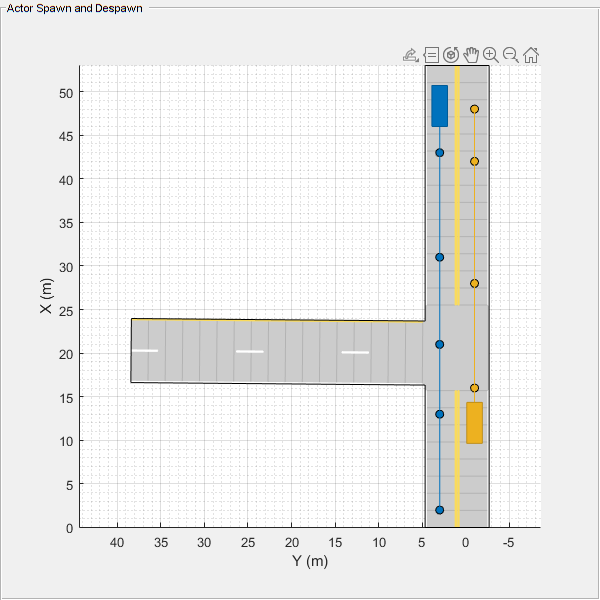

plot(scenario,'Waypoints','on','Parent',hPlt)
while advance(scenario)
    pause(0.1)
end

*Copyright 2020 The MathWorks, Inc.*